# Rezolvarea numerica a ecuatiilor neliniare

## Probleme

P1.

## Probleme practice

P1.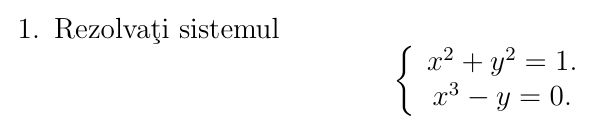

% sistem 1: x^2 + y^2 = 1, x^3 - y = 0
f1 = @(v) [v(1)^2 + v(2)^2 - 1; v(1)^3 - v(2)];
J1 = @(v) [2*v(1), 2*v(2); 3*v(1)^2, -1];
x0_1 = [0.7; 0.7];
eps = 1e-8;
Nmax = 30;

sol_newton_1 = newton_sistem(f1, J1, x0_1, eps, Nmax)

sol_newton_1 =     0.8260
    0.5636


sol_succesive_1 = aproximatii_succesive_sistem(f1, J1, x0_1, eps, Nmax)

sol_succesive_1 =     0.8260
    0.5636


P2.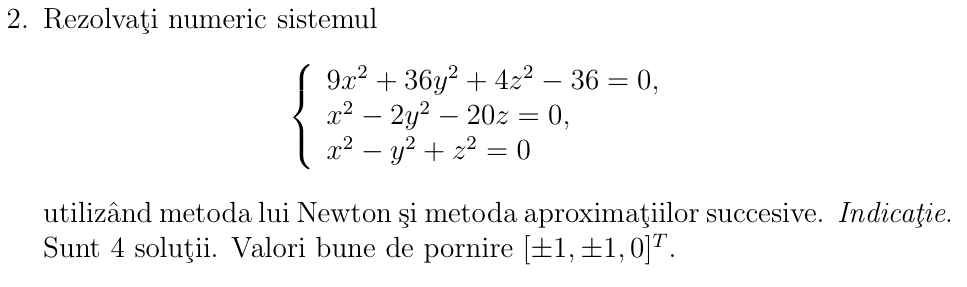

% definire sistem si jacobian
f = @(v) [9*v(1)^2 + 36*v(2)^2 + 4*v(3)^2 - 36;
          v(1)^2 - 2*v(2)^2 - 20*v(3);
          v(1)^2 - v(2)^2 + v(3)^2];
J = @(v) [18*v(1), 72*v(2), 8*v(3);
          2*v(1), -4*v(2), -20;
          2*v(1), -2*v(2), 2*v(3)];

% valori de pornire
start_points = [1 1 0; -1 1 0; 1 -1 0; -1 -1 0]';

eps = 1e-8;
Nmax = 30;

% calculam toate solutiile cu metoda Newton
disp('Solutii cu metoda Newton:')

Solutii cu metoda Newton:


for k = 1:4
    sol = newton_sistem(f, J, start_points(:,k), eps, Nmax);
    disp(sol)
end

    0.8936
    0.8945
   -0.0401

   -0.8936
    0.8945
   -0.0401

    0.8936
   -0.8945
   -0.0401

   -0.8936
   -0.8945
   -0.0401




% calculam toate solutiile cu metoda aproximatiilor succesive
disp('Solutii cu metoda aproximatiilor succesive:')

Solutii cu metoda aproximatiilor succesive:


for k = 1:4
    sol = aproximatii_succesive_sistem(f, J, start_points(:,k), eps, Nmax);
    disp(sol)
end

    0.8936
    0.8945
   -0.0401

   -0.8936
    0.8945
   -0.0401

    0.8936
   -0.8945
   -0.0401

   -0.8936
   -0.8945
   -0.0401

